# **Lab 6**

**Problem 1**

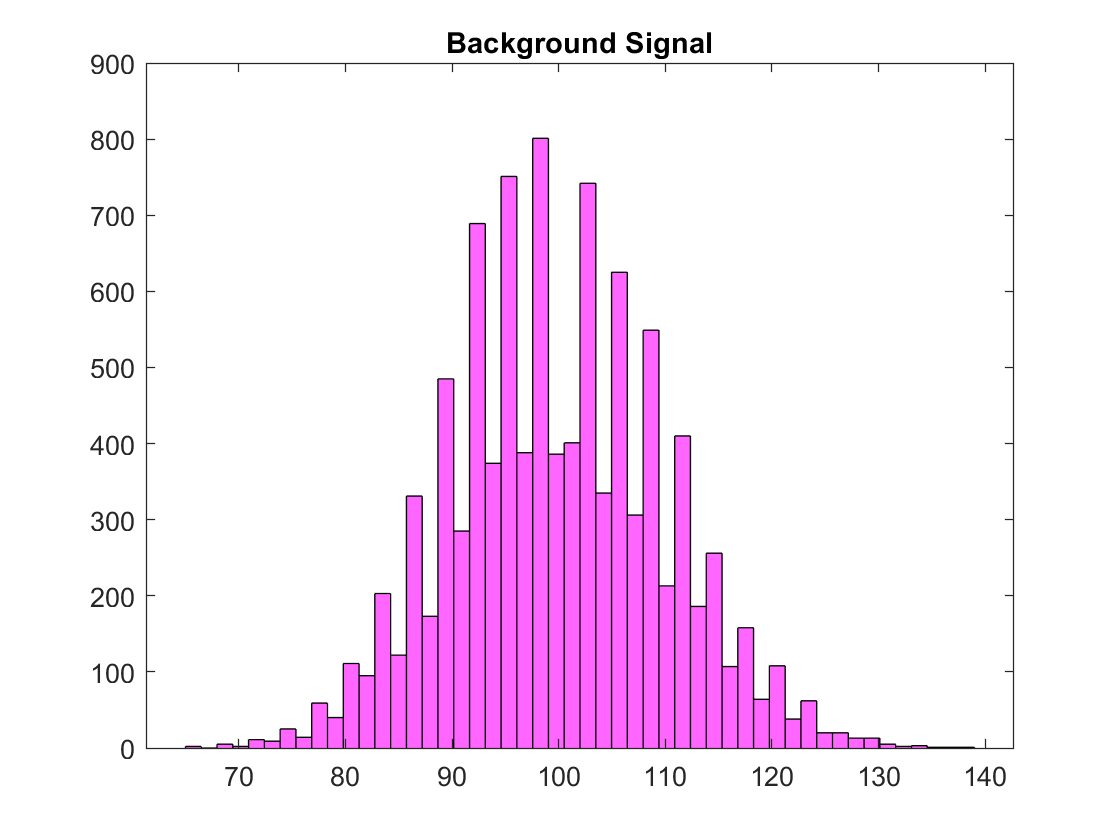

clear all; close all; clc;
lambda = 100;
x = 1:10000;
for i= 1:length(x)
    noise(i) = poissrnd(lambda);
end
histogram(noise, 50,"FaceColor",[1 0 1])
title('Background Signal')

sigma = std(noise)

sigma = 9.9387

fiveSigma = 5*sigma;

The 5 sigma sensitivity threshhold is then between values of 50 and 150 (lambda +/- fiveSigma)

**Problem 2**

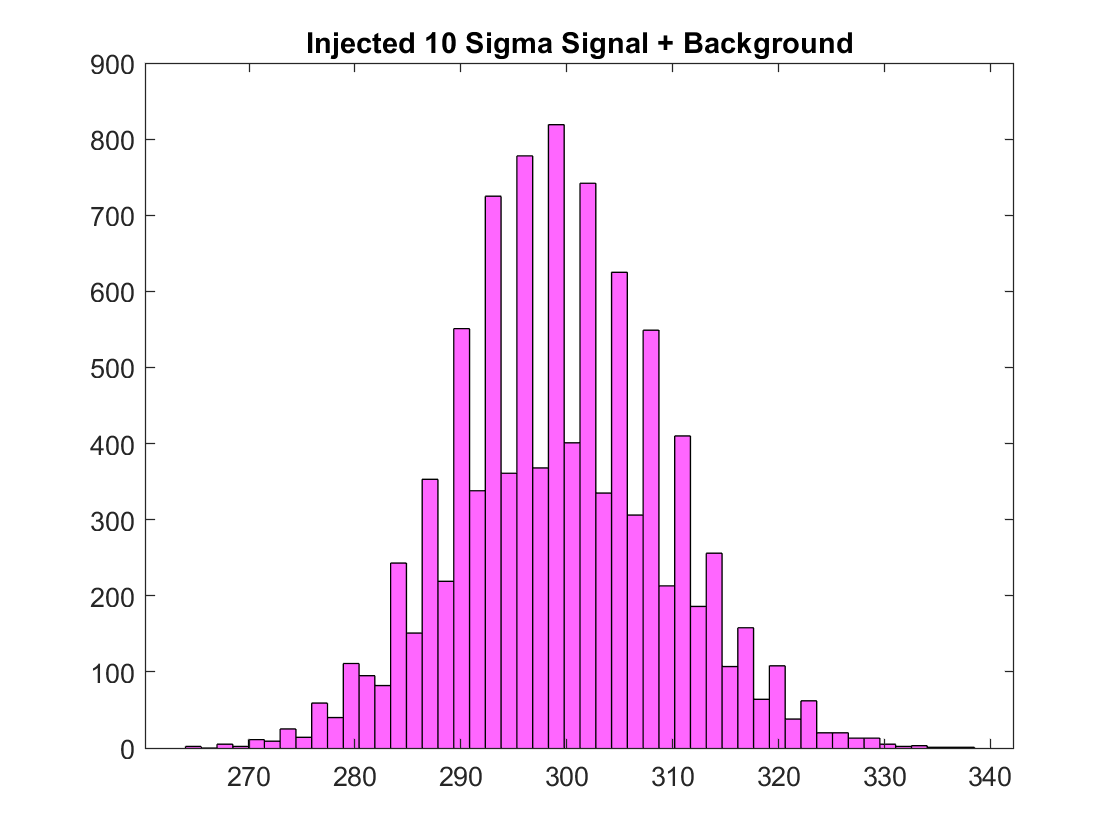

y(1) = 0;
for i=1:10000
    y(i)=noise(i) + (lambda+10*sigma);
end
histogram(y, 50,"FaceColor", [1 0 1])
title('Injected 10 Sigma Signal + Background')

a) The injected signal is brighter by a median of lambda = 100 (the median is now centered at 300 instead of 200 injected signal). It has a Poisson shape which is expected since Poisson noise was added.

b) Observed value is much more likely to be stronger than true injected signal: the background noise is added to the injected signal and that noise is non-negative with a median of 100. Therefore the distribution of the observed signal is skewed to the right. It is **bigger **than the injected signal and** not symmetric**.

**Problem 3**

I chose to inject a distribution of values ranging from 0 to 400. It is 30 sigma to the right and 10 sigma to the left. (We figured the sigma to be around 10 in Problem 1)

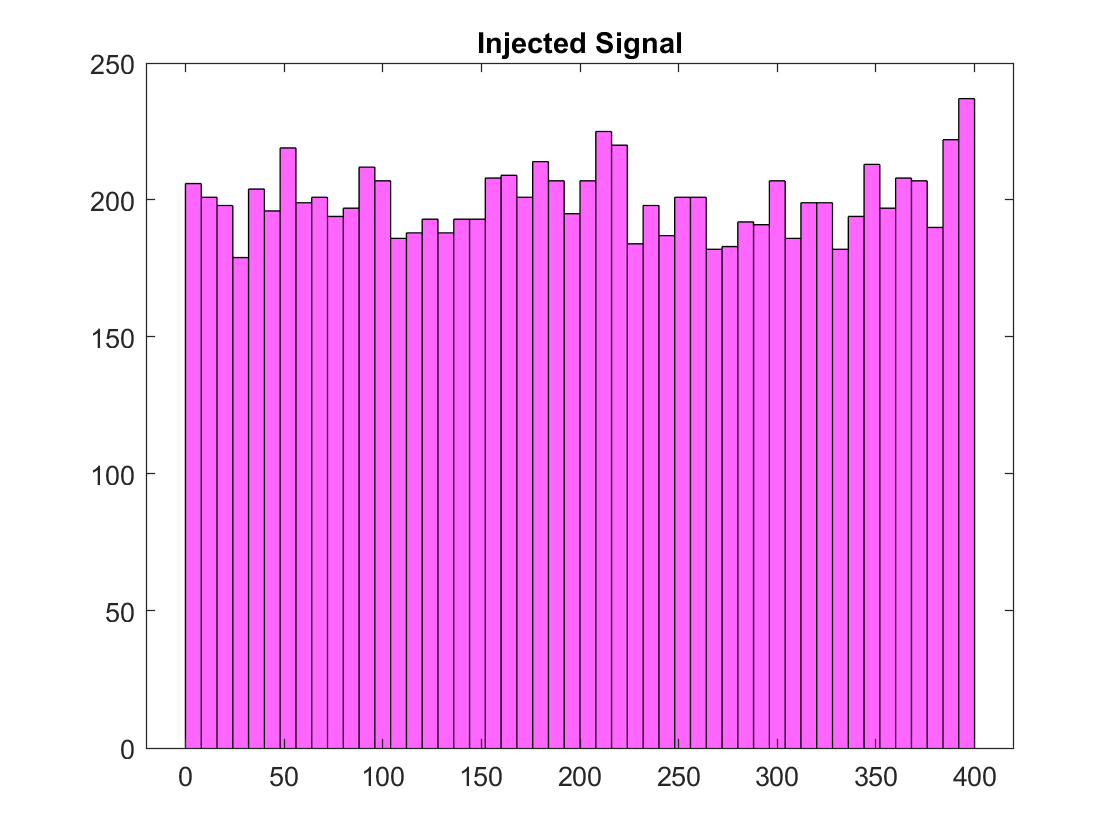

injectedSignal(1)=0;
for i = 1:10000
    injectedSignal(i) = 400*rand(1);
end
histogram(injectedSignal, 50, "FaceColor",[1 0 1])
title ('Injected Signal')

Observed signal is a combination of the noise and the injected signal. Plotting the observed signal we can see that there is almost no values of 0 because the noise added has an average of 100 that is added to the injected signal, and there are also signals that extend to 500 and beyound since the max injected signal is 400, and a possible backround noise addition can be in the range 50-150 on average.

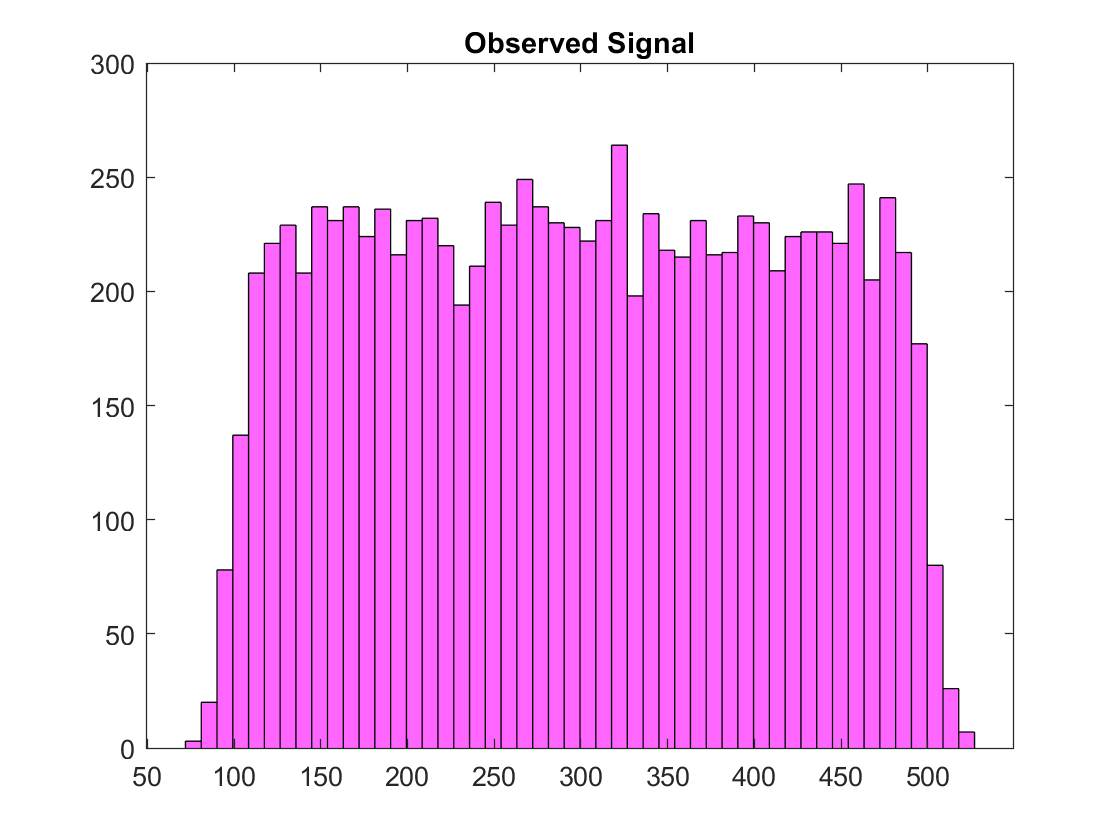

observedSignal = noise+injectedSignal;
histogram(observedSignal,50,"FaceColor",[1 0 1])
title 'Observed Signal'

Now, plotting observed signal vs injected signal, we can see that while the observed signal is directly proportional to the injected signal, it has a Poisson noise. The formula seems to follow

obs = inj + poisson noise

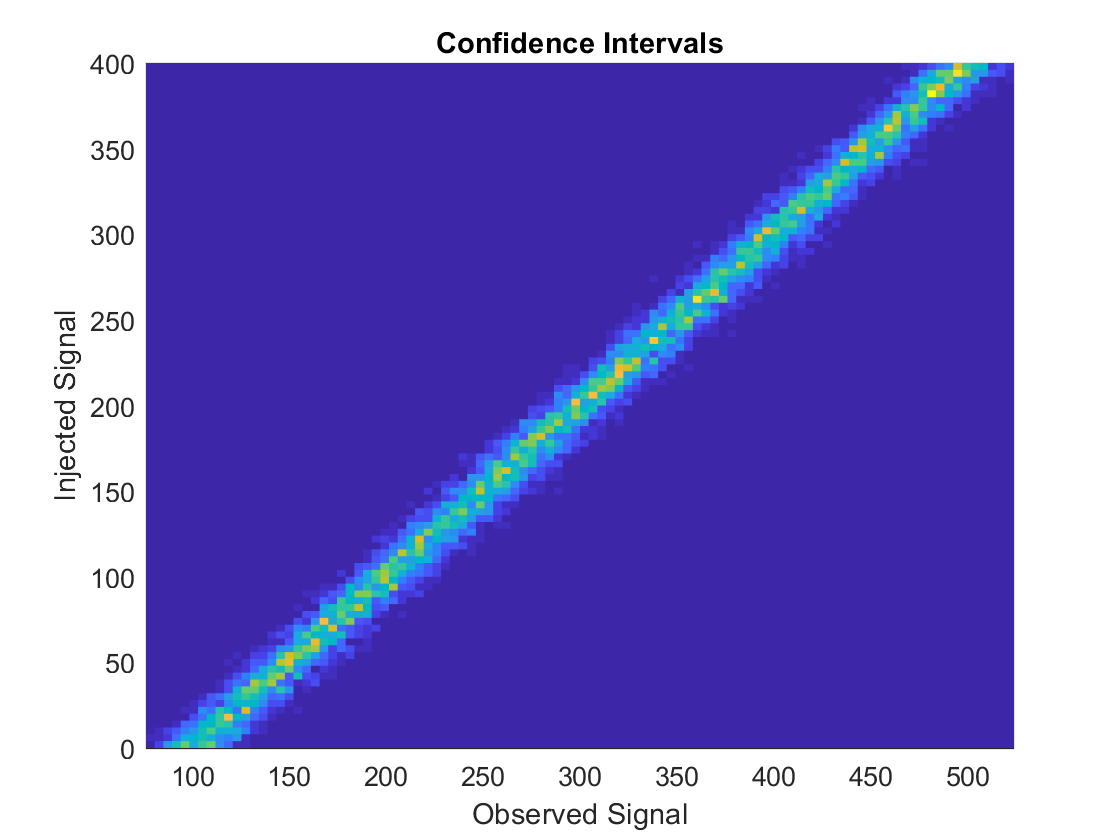

histogram2(observedSignal, injectedSignal,100,'DisplayStyle','tile','ShowEmptyBins','on')
xlabel 'Observed Signal'
ylabel 'Injected Signal'
title 'Confidence Intervals'

b) For a single power injected signal, the observed signal is going to be similar to the one in problem 2:

we find index of the observed signal with value of lambda+10*sigma = 200 and plot the 